## Initialize the FMCW Radar Computations

clear;
simulator = Simulator_revB();
%file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/B210_params.json";
% file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/B210_params_highBW.json";
% file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/B210_params_highvres.json";
 file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/B210_params_lowBW.json";
% file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/B210_params_sensing_system.json";
% file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/X310_params_100MHzBW.json";
% file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/realistic_params.json";
simulator.load_params_from_JSON(file_path);

%apply timing offsets as desired
simulator.Victim.timing_offset_us = 0;
simulator.Attacker.Subsystem_tracking.timing_offset_us = 0;

%configure the FMCW parameters
simulator.configure_FMCW_Radar_parameters();

%load default attacker, and victim positions and velocities
simulator.load_usrp_attacker_and_victim_position_and_velocity();
simulator.load_target_realistic();

%print out key parameters
simulator.Victim.print_chirp_parameters;

Chirp Parameters
	 Start Frequency: 		 1.50 GHz
	 Frequency Slope: 		 1.00 MHz/us
	 Idle Time: 			 18.44 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.56 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.20 MSps
	 Ramp End Time: 		 26.56 us
	 Chirp Tx Bandwidth: 		 26.56 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 20.00 us
	 Chirp Cycle Time: 		 45.00 us
	 Chirp Wavelength: 		 199.86 mm



simulator.Victim.print_frame_parameters;

Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 11.52 ms


simulator.Victim.print_performance_specs;

Performance Specifications
	 Max Range 			 479.67 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 1110.34 m/s
	 Velocity Resolution 		 8.67 m/s


simulator.Victim.print_FMCW_specs;

FMCW Specifications
	 FMCW sampling rate 		 28.80 MHz
	 Downsampling factor 		 9
	 Sweep time 			 26.56 us
	 Samples per chirp 		 1296.00 


### Initialize the Attacker

%initialize the attacker parameters
frames_to_compute = 30;
simulator.Attacker.initialize_attacker(...
                        simulator.Victim.FMCW_sampling_rate_Hz * 1e-6,...
                        simulator.Victim.StartFrequency_GHz,...
                        simulator.Victim.Chirp_Tx_Bandwidth_MHz);

%initialize the sensing subsystem's debugger
simulator.Attacker.Subsystem_spectrum_sensing.initialize_debugger(1,simulator.Victim,frames_to_compute);


% %for use in the simulink model
% fft_size = simulator.Attacker.Subsystem_spectrum_sensing.spectogram_params.fft_size;
% captured_chirps_buffer_size = simulator.Attacker.Subsystem_spectrum_sensing.chirp_tracking.captured_chirps_buffer_size;
% 
% %linear model computations in simulink
% max_num_clusters = simulator.Attacker.Subsystem_spectrum_sensing.clustering_params.max_num_clusters;
% threshold = simulator.Attacker.Subsystem_spectrum_sensing.clustering_params.min_num_points_per_cluster;
% % half_fft_size = simulator.Attacker.Subsystem_spectrum_sensing.spectogram_params.fft_size/2;

%initialize the attacker
simulator.Attacker.Subsystem_attacking.set_attacker_parameters(25,5,"target");

## Configure the Tx Data File

%save the full chirp as a binary file
path = "/home/david/Documents/MATLAB_generated/chirp_full.bin";
fileID = fopen(path,'w');
data = 0.3 *double(simulator.Victim.chirp);
fwrite(fileID,reshape([real(data),imag(data)].',[],1), 'float32');
fclose(fileID);

## Plot Tx Chirp to confirm correctness

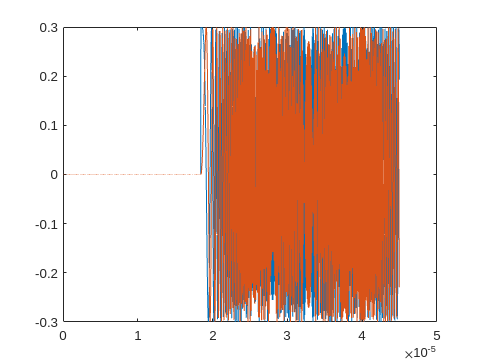

%plot the chirp signal
t = 0:simulator.Victim.FMCW_sampling_period_s:...
    simulator.Victim.ChirpCycleTime_us * 1e-6 - ...
    simulator.Victim.FMCW_sampling_period_s;
plot(t,real(data),t,imag(data))

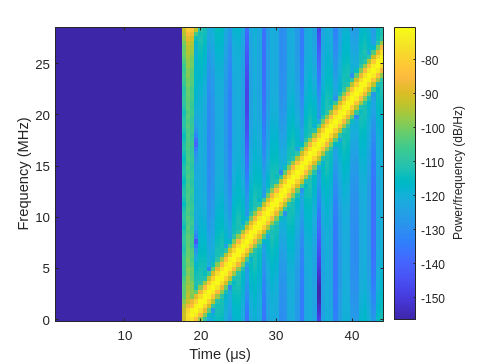

spectrogram(data,64,48,64,simulator.Victim.FMCW_sampling_rate_Hz,'yaxis')

## Read the Rx Data File

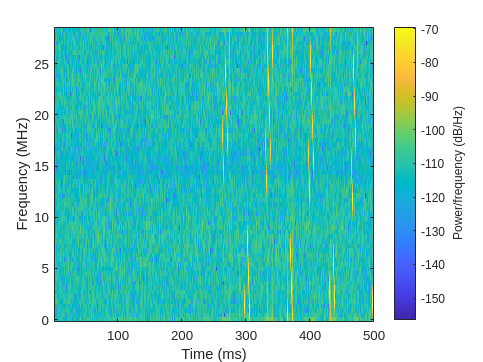

%to open a file from the GNU radio saved to a binary file
num_chirps = simulator.Victim.NumChirps;
samples_per_chirp = simulator.Victim.ChirpCycleTime_us * 1e-6 * simulator.Victim.FMCW_sampling_rate_Hz;
path = "/home/david/Documents/MATLAB_generated/sensing_stream.bin";
fileID = fopen(path,'r');
read_data = fread(fileID,'float');

%convert to complex values
read_data = reshape(read_data,2,[]).';
read_data = read_data(:,1) + 1j * read_data(:,2);

%sort into samples per buffer
spb = 2040;

num_samples_to_add = mod(size(read_data,1),spb);
if num_samples_to_add > 0
    sample_to_add = zeros(num_samples_to_add,1);
    read_data = [read_data;sample_to_add];
end

%generate a spectogram of the data to confirm correctness
spectrogram(read_data,64,48,64,simulator.Victim.FMCW_sampling_rate_Hz,'yaxis')

### Reshape the data to be processed by the sensing subsystem

%reshape the data into the correct format
read_data = reshape(read_data,spb,[]).';
%disp(read_data);
fclose(fileID);

%process the data

for i = 1:size(read_data,1)
    
    %update positions
    [victim_pos, victim_vel,attacker_pos, attacker_vel, tgt_pos,tgt_vel] = ...
        simulator.FMCW_determine_positions_and_velocities(...
        simulator.Victim.current_frame,simulator.Victim.num_samples_sent);
    
    %attacker determines relative position and velocity of the victim
    simulator.Attacker.update_victim_pos_and_velocity(attacker_pos,victim_pos,attacker_vel, victim_vel);
    
    %receive the signal in the attacker
    received_sig = read_data(i,:);
    simulator.Attacker.receive_signal(received_sig);
end

% %print out the relevant information
fprintf("Average Frame Duration: %5.3f us",simulator.Attacker.Subsystem_spectrum_sensing.frame_tracking.average_frame_duration);

Average Frame Duration: 33339.899 us

fprintf("Average Chirp Duration: %3.3f us",simulator.Attacker.Subsystem_spectrum_sensing.frame_tracking.average_chirp_duration);

Average Chirp Duration: 39.177 us

fprintf("Average Slope: %1.3f MHz/us",simulator.Attacker.Subsystem_spectrum_sensing.frame_tracking.average_slope);

Average Slope: 0.997 MHz/us